## Problem 1

Eric Nguyen

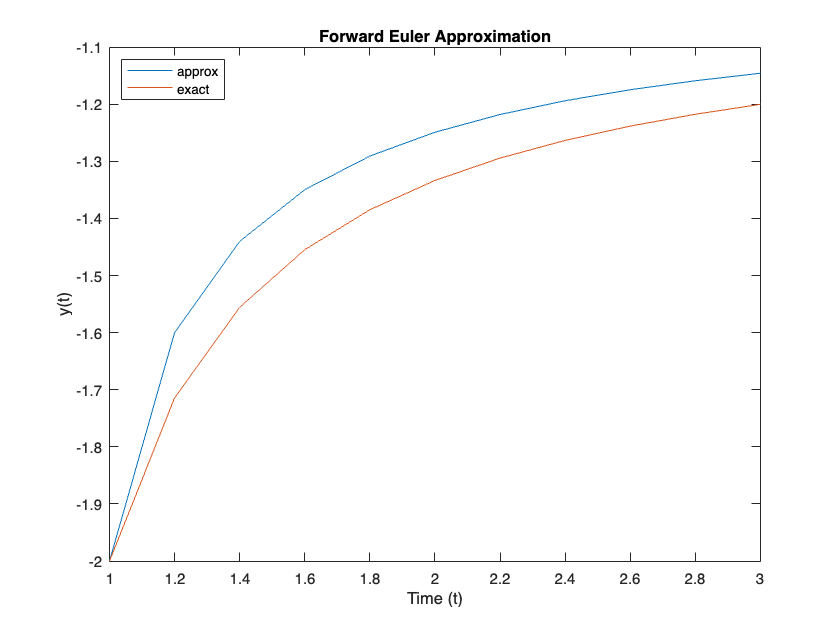

f = @(t,y) t.^(-1) .* (y.^2 + y);
y = @(t) (2.*t) ./ (1 - 2.*t);
ts = 1:0.2:3;
pts = forwardeuler(f,-2,1,3,10);
plot(pts(:,1), pts(:,2))
hold on
plot(ts, y(ts))
legend({'approx','exact'},'Location','northwest')
xlim([1 3])
xlabel('Time (t)')
ylabel('y(t)')
title('Forward Euler Approximation')
hold off

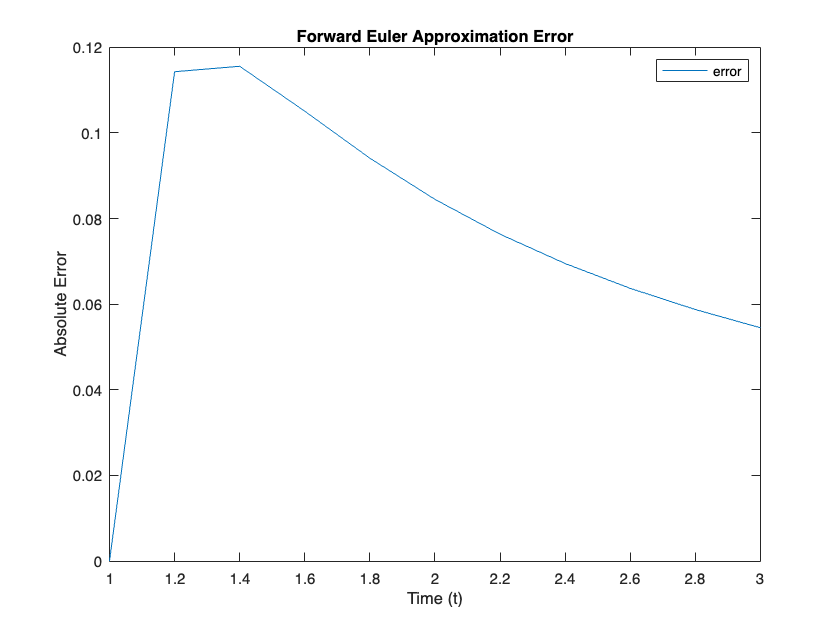

err = abs(y(ts) - pts(:,2)');
plot(ts,err)
xlabel('Time (t)')
ylabel('Absolute Error')
title('Forward Euler Approximation Error')
legend('error')

The approximation error decreases over time since the slope of the function is decreasing over time. Each step has an error of at least $h^2 = (0.2)^2 = 0.04$.

function pts = forwardeuler(f,y0,t0,tf,N)
    h = (tf - t0) / N;
    pts = zeros(N+1,2);
    pts(1,1) = t0;
    pts(1,2) = y0;
    for i=2:(N+1)
        pts(i,2) = y0 + h*f(t0,y0);
        y0 = pts(i,2);
        t0 = t0 + h;
        pts(i,1) = t0;
    end
end